# IMU Error Analysis

David Olson, 18 Feb 21

This script serves as a guide for determining the effects errors in an IMU will have on a final localization solution. This analysis should make clear how much of an impact each error source contributes, and can help prioritize what error sources are worth fighting in INS solutions.  

% Begin Script
close all
clear all
clc

% Load IMU Calibration Parameters
load("IMU_Cal_Const_Error_Sources.mat")
load("IMU_Cal_Varying_Error_Sources.mat")

The data used in this analysis results from calibration parameters captured in the testing of a Vector-Nav VN200 IMU.   While this analysis is not specific to any vehicle, the parameters assumed below just so happen to match what is achieved by the Quanser Qbot2.  These average accelerations and angular velocities are the averages seen when the Qbot2 travels in a $1m$ box.  

% Set Assumed Constants -- set to characteristics seen in qbot2_motion_gen.m
t = 30 * 60;                          % seconds
avg_accel = 0.03429;                  % m/s^2
avg_angular_rate = 0.26169;           % rad/s
% t = 180;                            % seconds
% avg_accel = 1.5;                    % m/s^2
% avg_angular_rate = pi/6;            % rad/s

## Accelerometer Error Analysis

The accelerometer, which produces the specific force measurement $\tilde{{\overrightarrow{f} }_{\textrm{ib}\;}^b }$, is subject to the following errors:

- Fixed Bias                                  $\left({\overrightarrow{b} }_{a,\textrm{FB}} \right)$

- Bias Stability $\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left({\overrightarrow{b} }_{a,\textrm{BS}} \right)$           **ASW: is this the run-to-run bias instability?**

- Bias Instability                             $\left({\overrightarrow{b} }_{a,\textrm{BI}} \right)$          

- Scale Factor & Misalignment $\;\;\;\;\;\;\;\;\left(M_a \right)$

- White Noise                                 $\left(\overrightarrow{w_a } \right)$

Each of these errors is accounted for in the following error model:


$$M_{a\;} =\left\lbrack \begin{array}{ccc}
s_{a,x}  & m_{a,\textrm{xy}}  & m_{a,\textrm{xz}} \\
m_{a,\textrm{yx}}  & s_{a,y}  & m_{a,\textrm{yz}} \\
m_{a,\textrm{zx}}  & m_{a,\textrm{zy}}  & s_{a,z} 
\end{array}\right\rbrack$$



$${\overrightarrow{b} }_a =$$

$${\overrightarrow{b} }_{a,\textrm{FB}} +$$

$${\overrightarrow{b} }_{a,\textrm{BS}} +$$

$${\overrightarrow{b} }_{a,\textrm{BI}}$$


${\overrightarrow{b} }_{a,\textrm{BI}} \left(k\right)=$${\overrightarrow{b} }_{a,\textrm{BI}} \left(k-1\right)e^{\frac{-\textrm{dt}}{\tau_a }} +{\overrightarrow{\eta \;} }_{a,\textrm{BI}}$    where ${\overrightarrow{\eta \;} }_{a,\textrm{BI}} =N\left\lbrack 0,\sigma {\;}_{a,\textrm{BI}} \right\rbrack$


$$\tilde{{\overrightarrow{f} }_{\textrm{ib}\;}^b } ={\overrightarrow{b} }_a +\left(I_{3\textrm{x3}} +M_a \right){\overrightarrow{f} }_{\textrm{ib}\;}^b +$$

$${\overrightarrow{w} }_a$$


### Accelerometer Error Effects

The following analysis picks apart each accelerometer error source and determines its effect on the final position error.  The computations performed are not intended to cover every possible detail, but rather serve as a rough guideline on the severity of each error.  

This analysis considers a worst case scenario to simplify computations.  Individual errors on each axis are RSS'd (root of the sum on the squares) together to keep each contribution independant.  For a highly-detailed analysis, a monte-carlo expirement should be considered to verify the computations performed here.  

Using the calibration parameters taken from real Vector-Nav VN-200 testing, each error source is compared accordingly below. 

#### Accelerometer Bias Effects

Biases in the accelerometer are integrated twice, once from acceleration to velocity, and once again from velocity to position.  Consider a single-dimensional case in which a vehicle remains perfectly still, and a bias $b_a$ is measured in error.  The error $e_x$, where "x" could be acceleration, velocity, or position.  Note that this bias $b_a$ could be the fixed bias, the bias stability, the bias instability, or the sum of some combination of these.  


$$\begin{array}{l}
e_a \left(t\right)=b_a \\
e_v \left(t\right)=\int b_a \;\textrm{dt}=b_a \;t\\
e_r \left(t\right)=\int b_a \;\;t\;\textrm{dt}=b_a \;\frac{t^2 }{2}
\end{array}$$
 

For bias instability, a constant $1\sigma \;$value is used as a worst case scenario.  Each axis of each bias type is RSS'd together, then each bias type result is RSS'd together again for the final result.  

% Accelerometer Bias Error Analysis
b_a_FB = b_a_FB;              % ASW: I assume the units for b_a_FB are m/s^s       
b_a_BS = 0.0001 * ones(3, 1); % ASW: where does 0.0001 come from?
b_a_BI = sigma_n_accel;       % 1-sigma value of bias instability, for worst case scenario   % ASW: I assume the units for sigma_n_accel are m/s^s

% Total Bias
accel_FB_effect = norm((t^2/2) * b_a_FB);
accel_BS_effect = norm((t^2/2) * b_a_BS);
accel_BI_effect = norm((t^2/2) * b_a_BI);

% Accelerometer Bias Error Effect on Position
accel_all_bias_effect = sqrt(accel_FB_effect^2 + accel_BS_effect^2 + accel_BI_effect^2);
accel_BS_BI_effect = sqrt(accel_BS_effect^2 + accel_BI_effect^2);
fprintf('Error in Position due to all Accelerometer Biases for a run-time of %.1f hr:  %4.3f m', t/3600, accel_all_bias_effect)

Error in Position due to all Accelerometer Biases for a run-time of 0.5 hr:  230935.314 m

fprintf('Error in Position due to only Bias Stability and Bias Instability for a run-time of %.1f hr:  %4.3f m', t/3600, accel_BS_BI_effect)

Error in Position due to only Bias Stability and Bias Instability for a run-time of 0.5 hr:  745.733 m

#### Accelerometer Scale Factor Effects

Scale factor errors occur when the sensing axis measures a scaled version of the truth.  This difference between the scaled measurement and the truth undergoes the same double integration the the previous bias errors.  This can be seen in the generalization shown below.    


$$\begin{array}{l}
e_a \left(t\right)=\left(1+s_{a,x} \right)\;a_{\textrm{avg}} -a_{\textrm{avg}} ={a_{\textrm{avg}} \;s}_{a,x} \\
e_v \left(t\right)=\int {a_{\textrm{avg}} \;s}_{a,x} \;\textrm{dt}={a_{\textrm{avg}} \;s}_{a,x} \;\;t\\
e_r \left(t\right)=\int {a_{\textrm{avg}} \;s}_{a,x} \;\;t\;\textrm{dt}={a_{\textrm{avg}} \;s}_{a,x} \;\;\frac{t^2 }{2}
\end{array}$$
 

In the computation below, it is assumed that each axis undergoes the same acceleration as the other axes.  Each axis's scale factor final position error is RSS'd together.  While this is rarely true, it serves as a good approximation and generalization.  For a higher-detailed analysis, consider a monte carlo expirement.  

% Capture Scale Factor Error from the Misalignment Matrix
a_sf = zeros(3,1);
for ii = 1 : 3
    a_sf(ii) = M_a(ii,ii);
end

% Set Acceleration Vector (Reflecting Qbot2 Average Accelerations)
a_travel = avg_accel * ones(3,1);

% Determine Final Position Error
SF_error = (t^2/2) * (a_travel .* a_sf);
accel_sf_effect = norm(SF_error);
fprintf('Error in Position due to Accelerometer Scale Factor for a run-time of %.1f hr:  %4.3f m', t/3600, accel_sf_effect)

Error in Position due to Accelerometer Scale Factor for a run-time of 0.5 hr:  26.520 m

#### Accelerometer Misalignment Effects

Misalignment errors occur when the sensing axis of the accelerometer is not perflectly orthoginal to its other sensing axes.  The angle of intrusion, $\delta \;\theta {\;}_{a,\textrm{zx}}$ for example, describes the angle of the accelerometer z-axis's lean over the x-axis.  This means that only a component of the true measurement is captured due to the tilt of the sensing axis.  The measurement becomes $a_{\textrm{avg}} \cos \left(\delta \;\theta {\;}_{a,\textrm{zx}} \right)$, meaning the error introduced is $a_{\textrm{avg}} \sin \left(\delta \;\theta {\;}_{a,\textrm{zx}} \right)$.  These angles are generally very small, certianly enough to meet the criteria for the small angle approximation which then means $\sin \left(\delta \;\theta {\;}_{a,\textrm{zx}} \right)\approx m_{a,\textrm{zx}}$.  


$$\begin{array}{l}
e_a \left(t\right)=a_{\textrm{avg}} \;\sin \left(\delta \;\theta {\;}_{a,\textrm{zx}} \;\right)\approx a_{\textrm{avg}} \;m_{a,\textrm{zx}} \;\;\;\;\left(\textrm{small}\;\textrm{angle}\;\textrm{approximation}\right)\\
e_v \left(t\right)=\int a_{\textrm{avg}} \;m_{a,\textrm{zx}} \;\textrm{dt}=a_{\textrm{avg}} \;m_{a,\textrm{zx}} \;\;t\\
e_r \left(t\right)=\int a_{\textrm{avg}} \;m_{a,\textrm{zx}} \;t\;\textrm{dt}=a_{\textrm{avg}} \;m_{a,\textrm{zx}} \;\frac{t^2 }{2}
\end{array}$$
 

Each sensing axis can intrude into two different Cartesian axes, therefore the RSS of each misalignment for a sening axis is computed.  Then the misalignment error of each axis is RSS'd as well for the final result.  

% Compute the Mislaignment Error of each axis
e_a_x = avg_accel * (t^2/2) * sqrt(M_a(1,2)^2 + M_a(1,3)^2);
e_a_y = avg_accel * (t^2/2) * sqrt(M_a(2,1)^2 + M_a(2,3)^2);
e_a_z = avg_accel * (t^2/2) * sqrt(M_a(3,1)^2 + M_a(3,2)^2);
e_a = [e_a_x; e_a_y; e_a_z];
        
% Compute Resulting Final Position Error
accel_Ma_effect = norm(e_a);
fprintf('Error in Position due to Accelerometer Misalignment for a run-time of %.1f hr:  %4.3f m', t/3600, accel_Ma_effect)

Error in Position due to Accelerometer Misalignment for a run-time of 0.5 hr:  220.035 m

#### Accelerometer Velocity Random Walk (VRW) Effects

The accelerometer is also subject to noise.  When performing a power spectral density (PSD) of this noise, the noise is justifiably white.  When integrating this noise, this could lead to a random walk in terms of velocity.  The extent of this velocity random walk (VRW) is captured in the PSD in the following units:


$$\textrm{units}\left\lbrack \textrm{VRW}\right\rbrack =\frac{\frac{m}{s}}{\sqrt{\textrm{hr}}}$$


The furthest the random walk can extend depends on the amount of time passed.  Therefore, multiplying by the square root of the time duration determines the maximum possible velocity random walk value.  This is then integrated into position for the final resulting error.  This analysis is also considered a worst-case scenario as it is assumed the VRW grows to its maximum possible extent according to the amount of time that has passed. 

*** Note that in this case, the time $t$ is in hours, not seconds to account for the above units of the VRW ***


$$\begin{array}{l}
e_v \left(t\right)=\textrm{VRW}\sqrt{t}=\textrm{VRW}\;t^{\frac{1}{2}} \\
e_r \left(t\right)=\int \textrm{VRW}\;t^{\frac{1}{2}} \;\textrm{dt}=\textrm{VRW}\;\frac{2t^{\frac{3}{2}} }{3}
\end{array}$$


**ASW: I think this integral was missing 2/3**

Time is converted into hours, then the VRW extent is computed for each axis.  Each result is RSS'd together.  

% Convert Time into sqrt(hours)
t_sqrt_hours = t / sqrt(3600);

% Compute Final Position Error
%accel_VRW_effect = norm(accel_VRW * 2*t_sqrt_hours^(3/2)/3);  % ASW: updated to the above integral
accel_VRW_effect = norm(accel_VRW / sqrt(3600) * 2*t^(3/2)/3);  % ASW: careful with what time units you end up in
fprintf('Error in Position due to Accelerometer VRW for a run-time of %.1f hr:  %4.3f m', t/3600, accel_VRW_effect)

Error in Position due to Accelerometer VRW for a run-time of 0.5 hr:  182.614 m

### Comparison of Accelerometer Error Sources

Below is a bar graph comparing each error source's contribution to the overall error in final position.  

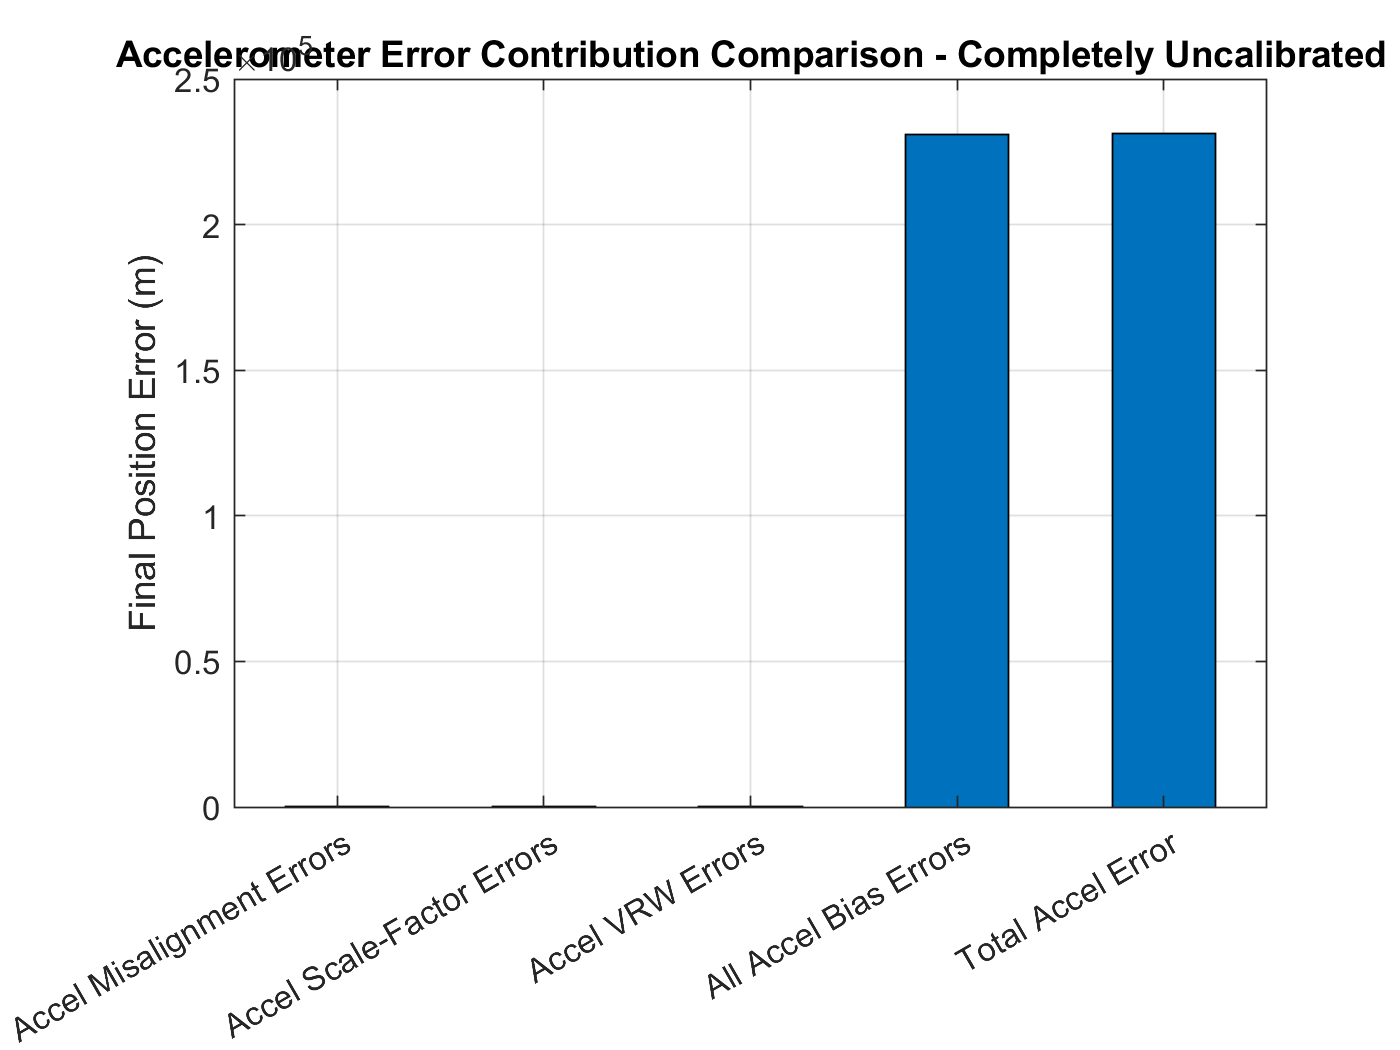

% Summing Up Final Errors
total_accel_error_1 = accel_all_bias_effect + accel_sf_effect + accel_Ma_effect + accel_VRW_effect;

% Creating the Bar Chart
accel_error_comp_1 = [accel_all_bias_effect, accel_sf_effect, accel_Ma_effect, accel_VRW_effect, total_accel_error_1];
labels = categorical({'All Accel Bias Errors', 'Accel Scale-Factor Errors', 'Accel Misalignment Errors', ...
          'Accel VRW Errors', 'Total Accel Error'});  
      
figure
bar(labels, accel_error_comp_1, 0.5);
title('Accelerometer Error Contribution Comparison - Completely Uncalibrated')
ylabel('Final Position Error (m)')
grid on

Below is the same graph but with the fixed bias removed.  It is a simple calibration to perform, and is typically the only calibration performed for simple expirements. 

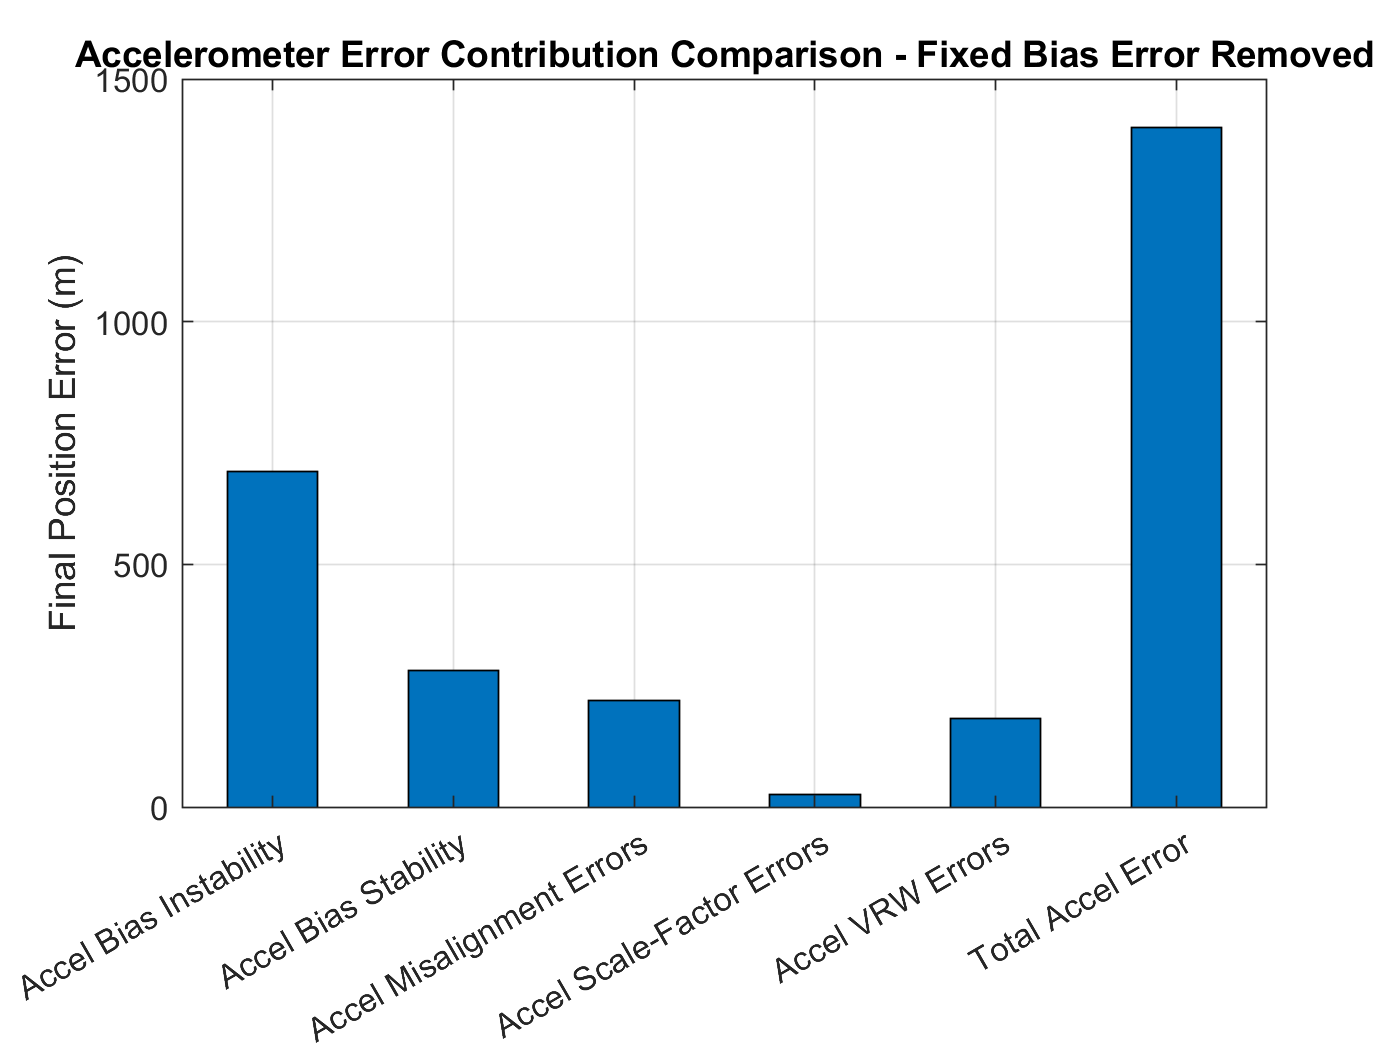

% Summing Up Final Errors
total_accel_error_2 = accel_BS_effect + accel_BI_effect + accel_sf_effect + accel_Ma_effect + accel_VRW_effect;

% Creating the Bar Chart
accel_error_comp_2 = [accel_BS_effect, accel_BI_effect, accel_sf_effect, accel_Ma_effect, accel_VRW_effect, total_accel_error_2];
labels = categorical({'Accel Bias Stability', 'Accel Bias Instability', 'Accel Scale-Factor Errors', 'Accel Misalignment Errors', ...
          'Accel VRW Errors', 'Total Accel Error'});  
      
figure
bar(labels, accel_error_comp_2, 0.5);
title('Accelerometer Error Contribution Comparison - Fixed Bias Error Removed')
ylabel('Final Position Error (m)')
grid on

## Gyroscope Error Analysis

The gyroscope, which produces the specific force measurement $\tilde{{\overrightarrow{\omega \;} }_{\textrm{ib}\;}^b }$, is subject to the following errors:

- Fixed Bias          $\left({\overrightarrow{b} }_{g,\textrm{FB}} \right)$

- Bias Stability $\;\;\;\;\;\;\;\left({\overrightarrow{b} }_{g,\textrm{BS}} \right)$    **ASW: is this the run-to-run bias instability?**

- Bias Instability    $\left({\overrightarrow{b} }_{g,\textrm{BI}} \right)$

- Misalignment $\;\;\;\;\;\;\;\;\left(M_g \right)$

- White Noise         $\left(\overrightarrow{w_g } \right)$

- Gyro Sensitivity    $\left(G_g \right)$  (ignored in this discussion, for now)

Each of these errors is accounted for in the following error model:


$$M_{g\;} =\left\lbrack \begin{array}{ccc}
s_{g,x}  & m_{g,\textrm{xy}}  & m_{g,\textrm{xz}} \\
m_{g,\textrm{yx}}  & s_{g,y}  & m_{g,\textrm{yz}} \\
m_{g,\textrm{zx}}  & m_{g,\textrm{zy}}  & s_{g,z} 
\end{array}\right\rbrack$$



$${\overrightarrow{b} }_g =$$

$${\overrightarrow{b} }_{g,\textrm{FB}} +$$

$${\overrightarrow{b} }_{g,\textrm{BS}} +$$

$${\overrightarrow{b} }_{g,\textrm{BI}}$$


${\overrightarrow{b} }_{g,\textrm{BI}} \left(k\right)=$${\overrightarrow{b} }_{g,\textrm{BI}} \left(k-1\right)e^{\frac{-\textrm{dt}}{\tau {\;}_g }} +{\overrightarrow{\eta \;} }_{g,\textrm{BI}}$    where ${\overrightarrow{\eta \;} }_{g,\textrm{BI}} =N\left\lbrack 0,\sigma {\;}_{g,\textrm{BI}} \right\rbrack$


$$\tilde{{\overrightarrow{\omega \;} }_{\textrm{ib}\;}^b } ={\overrightarrow{b} }_g +\left(I_{3\textrm{x3}} +M_g \right){\overrightarrow{\omega \;} }_{\textrm{ib}\;}^b +G_g {\overrightarrow{f} }_{\textrm{ib}\;}^b +$$

$${\overrightarrow{w} }_g$$


### Gyroscope Error Effects

#### Gyroscope Bias Effects

Biases in the gyroscopes are integrated three times.   It first determines the amount of angle rotated in a time-step which then gets coupled into the acceleration, then integrated from acceleration to velocity, and once again from velocity to position.  Consider a single-dimensional case in which a vehicle remains perfectly still, and a bias $g$ is measured in error.  The error $e_x$, where "x" could be acceleration, velocity, or position.  Note that this bias $b_g$ could be the fixed bias, the bias stability, the bias instability, or the sum of some combination of these.  


$$\begin{array}{l}
\Delta \;\theta \;=\int_0^t b_g d\tau \;=b_g \;t\\
a_{\textrm{avg}} \sin \left(\Delta \;\theta \;\right)\approx a_{\textrm{avg}} \Delta \;\theta \;=a_{\textrm{avg}} {\;b}_g \;t
\end{array}$$



$$\begin{array}{l}
e_a \left(t\right)=a_{\textrm{avg}} {\;b}_g \;t\\
e_v \left(t\right)=\int a_{\textrm{avg}} {\;b}_g \;t\;\textrm{dt}=\frac{a_{\textrm{avg}} b_g t^2 }{2}\\
e_r \left(t\right)=\int \frac{a_{\textrm{avg}} b_g t^2 }{2}\;\textrm{dt}=\frac{a_{\textrm{avg}} b_g t^3 }{6}
\end{array}$$
 

For bias instability, a constant $1\sigma \;$value is used as a worst case scenario.  Each axis of each bias tye is RSS'd together, then each bias type result is RSS'd together again for the final result.  

% Gyroscope Bias Error Analysis
b_g_FB = b_g_FB;              
b_g_BS = 0.00001 * ones(3, 1);   % ASW: where does 0.0001 come from? 
b_g_BI = sigma_n_gyro;           % 1-sigma value of bias instability, for worst case scenario

% Total Bias
gyro_FB_effect = norm(avg_accel * (t^3/6) * b_g_FB);
gyro_BS_effect = norm(avg_accel * (t^3/6) * b_g_BS);
gyro_BI_effect = norm(avg_accel * (t^3/6) * b_g_BI);

% Gyroscope Bias Error Effect on Position
gyro_all_bias_effect = sqrt(gyro_FB_effect^2 + gyro_BS_effect^2 + gyro_BI_effect^2);
gyro_BS_BI_effect = sqrt(gyro_BS_effect^2 + gyro_BI_effect^2);
fprintf('Error in Position due to all Gyroscope Biases for a run-time of %.1f hr:  %4.3f m', t/3600, gyro_all_bias_effect)

Error in Position due to all Gyroscope Biases for a run-time of 0.5 hr:  553309.038 m

fprintf('Error in Position due to only Bias Stability and Bias Instability for a run-time of %.1f hr:  %4.3f m', t/3600, gyro_BS_BI_effect)

Error in Position due to only Bias Stability and Bias Instability for a run-time of 0.5 hr:  1371.424 m

#### Gyroscope Scale Factor Effects

On each sensing axis of the gyroscope, there is possibility for scale factor.  This is when the angular rate seen by the sensing axis is scaled slightly different due to imperfections in its manufacture. This causes the IMU axes to drift as time propagates, meaning that once the angular velocity components are integrated with their error, the accelerometer updates also drift further away from the truth.  The error in the accelerometer then is the component of the "sin()" of the angle drift.  Its full propagation is demonstrated below.  


$$\begin{array}{l}
\\
\Delta \;\omega \;={\left(1+s_{g,x} \right)\omega }_{\textrm{avg}} -\omega_{\textrm{avg}} =\omega_{\textrm{avg}} \;s_{g,x} \;\\
\Delta \;\theta \;=\int_0^t \omega_{\textrm{avg}} \;s_{g,x} \;d\tau \;=\omega_{\textrm{avg}} \;s_{g,x} \;t
\end{array}$$



$$\begin{array}{l}
e_a \left(t\right)=a_{\textrm{avg}} \sin \left(\Delta \;\theta \;\right)\approx a_{\textrm{avg}} \Delta \;\theta \;=a_{\textrm{avg}} \omega_{\textrm{avg}} \;s_{g,x} \;\;t\\
e_v \left(t\right)=\int a_{\textrm{avg}} \omega_{\textrm{avg}} \;s_{g,x} \;\;t\;\textrm{dt}=\frac{a_{\textrm{avg}} \omega_{\textrm{avg}} \;s_{g,x} \;\;t^2 }{2}\\
e_r \left(t\right)=\int \frac{a_{\textrm{avg}} \omega_{\textrm{avg}} \;s_{g,x} \;\;t^2 }{2}\;\textrm{dt}=\frac{a_{\textrm{avg}} \omega_{\textrm{avg}} \;s_{g,x} \;\;t^3 }{6}
\end{array}$$


In the computation below, it is assumed that each axis undergoes the same acceleration as the other axes.  Each axis's scale factor final position error is RSS'd together.  While this is rarely true, it serves as a good approximation and generalization.  For a higher-detailed analysis, consider a monte carlo expirement.   

% Capture Scale Factor Error
g_sf = zeros(3,1);
for ii = 1 : 3
    g_sf(ii) = M_g(ii,ii);
end

% Set Acceleration and Angular Velocity Vectors (Reflecting Qbot2 Box Path Accelerations and Rotation Rates)
a_travel = avg_accel * ones(3,1); 
w_travel = avg_angular_rate * ones(3,1);

% Determine Final Position Error
SF_error = (t^3/6) * (w_travel .* a_travel .* g_sf);
gyro_sf_effect = norm(SF_error);
fprintf('Error in Position due to Gyroscope Scale Factor for a run-time of %.1f hr:  %4.3f m', t/3600, gyro_sf_effect)

Error in Position due to Gyroscope Scale Factor for a run-time of 0.5 hr:  7182.773 m

#### Gyroscope Misalignment Effects

Misalignment errors occur when the sensing axis of the gyroscope is not perflectly orthoginal to its other sensing axes.  The angle of intrusion, $\delta \;\theta {\;}_{g,\textrm{zx}}$ for example, describes the angle of the gyroscope z-axis's lean over the x-axis.  This means that only a component of the true measurement is captured due to the tilt of the sensing axis.  The measurement becomes ${\omega \;}_{\textrm{avg}} \cos \left(\delta \;\theta {\;}_{g,\textrm{zx}} \right)$, meaning the error introduced is ${\omega \;}_{\textrm{avg}} \sin \left(\delta \;\theta {\;}_{g,\textrm{zx}} \right)$.  These angles are generally very small, certianly enough to meet the criteria for the small angle approximation which then means $\delta \;\theta {\;}_{g,\textrm{zx}} \approx m_{g,\textrm{zx}}$.  


$$\begin{array}{l}
\Delta \;\omega ={\omega \;}_{\mathrm{avg}} \mathrm{sin}\left(\delta \;\theta {\;}_{g,\mathrm{zx}} \right)\approx {\omega_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \\
\Delta \;\theta =\int_0^t {\omega_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} d\tau ={\omega_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t
\end{array}$$



$$\begin{array}{l}
e_a \left(t\right)=a_{\mathrm{avg}} \;\mathrm{sin}\left(\Delta \;\theta \;\right)\approx {{a_{\mathrm{avg}} \;\omega }_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t\\
e_v \left(t\right)=\int {{a_{\mathrm{avg}} \;\omega }_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t\;\mathrm{dt}=\frac{{{a_{\mathrm{avg}} \;\omega }_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t^2 }{2}\\
e_r \left(t\right)=\int \frac{{{a_{\mathrm{avg}} \;\omega }_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t^2 }{2}\;\mathrm{dt}=\frac{{{a_{\mathrm{avg}} \;\omega }_{\mathrm{avg}} \;m}_{g,\mathrm{zx}} \;t^3 }{6}
\end{array}$$


Each sensing axis can intrude into two different Cartesian axes, therefore the RSS of each misalignment for a sening axis is computed.  Then the misalignment error of each axis is RSS'd as well for the final result.  

% Compute the Mislaignment Error of each axis
e_g_x = avg_accel * avg_angular_rate * (t^3/6) * sqrt(M_g(1,2)^2 + M_g(1,3)^2);
e_g_y = avg_accel * avg_angular_rate * (t^3/6) * sqrt(M_g(2,1)^2 + M_g(2,3)^2);
e_g_z = avg_accel * avg_angular_rate * (t^3/6) * sqrt(M_g(3,1)^2 + M_g(3,2)^2);
e_g = [e_g_x; e_g_y; e_g_z];
        
% Compute Resulting Final Position Error
gyro_Mg_effect = norm(e_g);
fprintf('Error in Position due to Gyroscope Misalignment for a run-time of %.1f hr:  %4.3f m', t/3600, gyro_Mg_effect)

Error in Position due to Gyroscope Misalignment for a run-time of 0.5 hr:  87976.746 m

#### Gyroscope Angle Random Walk (ARW) Effects

The accelerometer is also subject to noise.  When performing a power spectral density (PSD) of this noise, the noise is justifyibly white.  When integrating this noise, this could lead to a random walk in terms of angle.  In this PSD, the extent of this angle random walk (ARW) is captured in the PSD in the following units:


$$\textrm{units}\left\lbrack \textrm{ARW}\right\rbrack =\frac{\deg }{\sqrt{\textrm{hr}}}$$


The furthest the random walk can extend depends on the amount of time passed.  Therefore, multiplying by the square root of the time duration determines the maximum possilbe angle random walk value.  This is then integrated twice into position for the final resulting error.  This analysis is also considered a worst-case scenario as it is assumed the ARW grows to its maximum possible extent according to the amount of time that has passed. 

*** Note that in this case, the time $t$ is in hours, not seconds to account for the above units of the ARW ***


$$\begin{array}{l}
\Delta \;\theta =\textrm{ARW}\sqrt{t}={\textrm{ARWt}}^{\frac{1}{2}} \\
e_a \left(t\right)={a_{\textrm{avg}} \;\sin \left(\Delta \;\theta \;\right)\approx \;a}_{\textrm{avg}} {\textrm{ARWt}}^{\frac{1}{2}} 
\end{array}$$



$$\begin{array}{l}
e_v \left(t\right)=\int a_{\textrm{avg}} \textrm{ARW}t^{\frac{1}{2}} \textrm{dt}=\frac{{2a}_{\textrm{avg}} {\textrm{ARWt}}^{\frac{3}{2}} }{3}\\
e_r \left(t\right)=\int \frac{{2a}_{\textrm{avg}} {\textrm{ARWt}}^{\frac{3}{2}} }{3}\;\textrm{dt}=\frac{{4a}_{\textrm{avg}} {\textrm{ARWt}}^{\frac{5}{2}} }{15}
\end{array}$$


Time is converted into hours, then the VRW extent is computed for each axis.  Each result is RSS'd together.  

% Convert gyro ARW from degrees to radians
gyro_ARW_rad = gyro_ARW * pi/180;

% Convert time into sqrt(hours)
t_sqrt_hours = t / sqrt(3600);

% Compute Final Position Error
%gyro_ARW_effect = norm((4/15) * avg_accel * gyro_ARW_rad * t_sqrt_hours^(5/2));
gyro_ARW_effect = norm((4/15) * avg_accel * gyro_ARW_rad / sqrt(3600) * t^(5/2));  % ASW: be care with what units you end up in
fprintf('Error in Position due to Gyroscope ARW for a run-time of %.1f hr:  %4.6f m', t/3600, gyro_ARW_effect)

Error in Position due to Gyroscope ARW for a run-time of 0.5 hr:  208.616660 m

### Comparison of Gyroscope Error Sources

Below is a bar graph comparing each error source's contribution to the overall error in final position.  

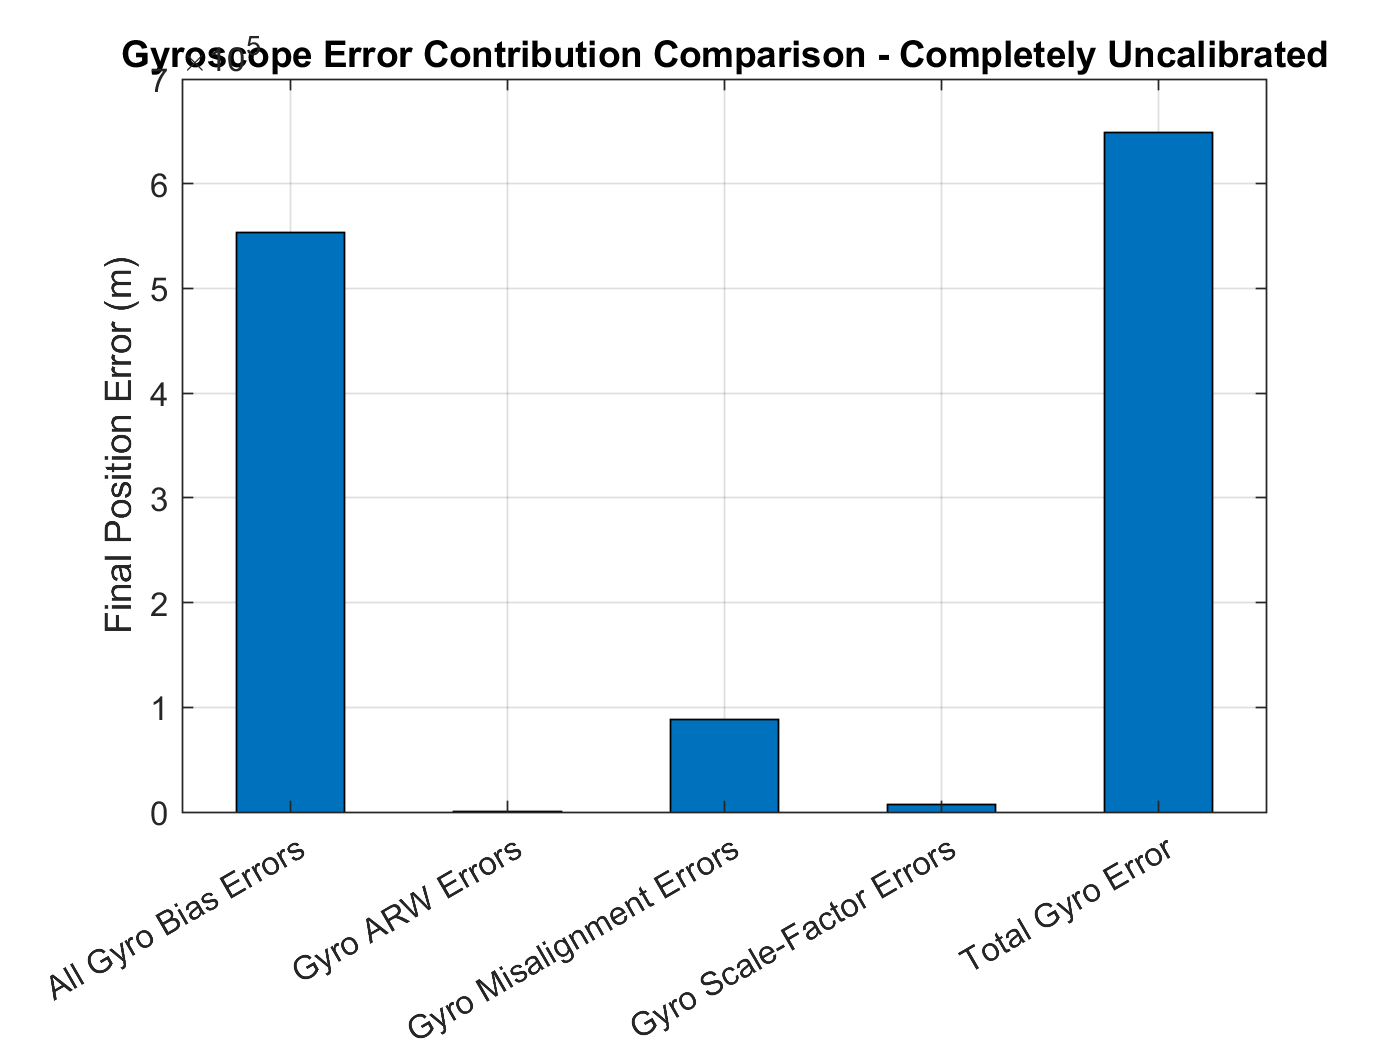

% Summing Up Final Errors
total_gyro_error_1 = gyro_all_bias_effect + gyro_sf_effect + gyro_Mg_effect + gyro_ARW_effect;

% Creating the Bar Chart
gyro_error_comp_1 = [gyro_all_bias_effect, gyro_sf_effect, gyro_Mg_effect, gyro_ARW_effect, total_gyro_error_1];
labels = categorical({'All Gyro Bias Errors', 'Gyro Scale-Factor Errors', 'Gyro Misalignment Errors', ...
          'Gyro ARW Errors', 'Total Gyro Error'});  
      
figure
bar(labels, gyro_error_comp_1, 0.5);
title('Gyroscope Error Contribution Comparison - Completely Uncalibrated')
ylabel('Final Position Error (m)')
grid on

Below is the same graph but with the fixed bias removed.  It is a simple calibration to perform, and is typically the only calibration performed for simple expirements. 

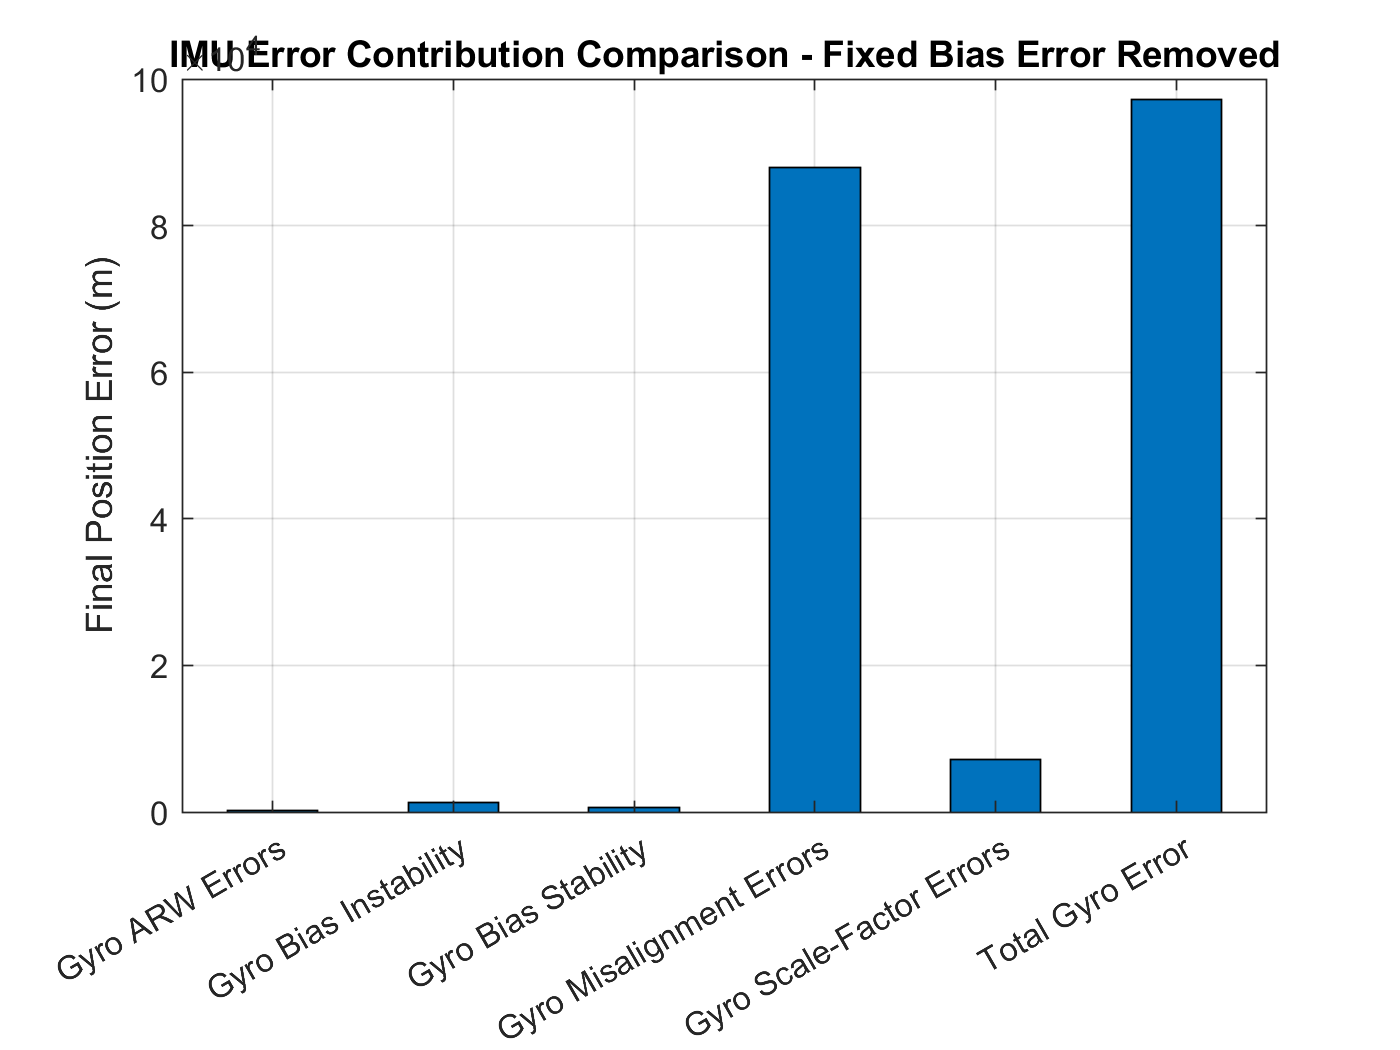

% Summing Up Final Errors
total_gyro_error_2 = gyro_BS_effect + gyro_BI_effect + gyro_sf_effect + gyro_Mg_effect + gyro_ARW_effect;

% Creating the Bar Chart
gyro_error_comp_2 = [gyro_BS_effect, gyro_BI_effect, gyro_sf_effect, gyro_Mg_effect, gyro_ARW_effect, total_gyro_error_2];
labels = categorical({'Gyro Bias Stability', 'Gyro Bias Instability', 'Gyro Scale-Factor Errors', 'Gyro Misalignment Errors', ...
          'Gyro ARW Errors', 'Total Gyro Error'});  
      
figure
bar(labels, gyro_error_comp_2, 0.5);
title('IMU Error Contribution Comparison - Fixed Bias Error Removed')
ylabel('Final Position Error (m)')
grid on

## Comparison of all the IMU Errors

### Completely Uncalibratied IMU Error Comparison

When the IMU is completely uncalibrated, how does each error source impact the resulting final localization solution?  

See the bar graph below to make the comparison.  Note that the fixed bias in each sensor contributes a large majority of the final position error.  

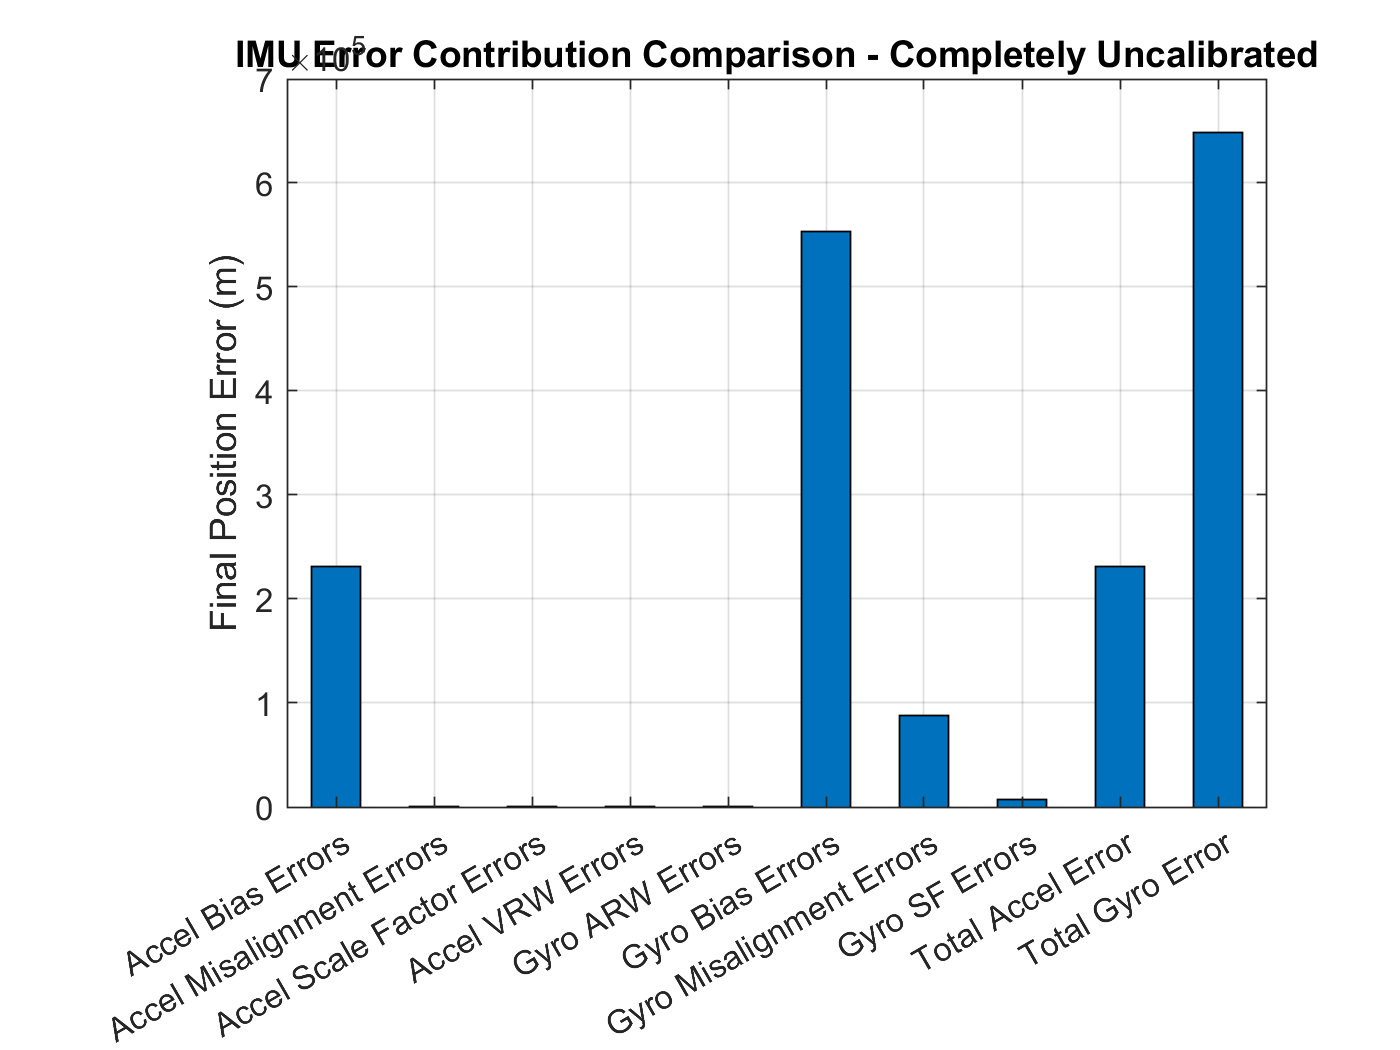

% Summing Up Final Errors
total_accel_error = accel_all_bias_effect + accel_sf_effect + accel_Ma_effect + accel_VRW_effect;
total_gyro_error = gyro_all_bias_effect + gyro_sf_effect + gyro_Mg_effect + gyro_ARW_effect;

% Creating the Bar Chart
error_comp = [accel_all_bias_effect, accel_sf_effect, accel_Ma_effect, accel_VRW_effect, ...
              gyro_all_bias_effect, gyro_sf_effect, gyro_Mg_effect, gyro_ARW_effect, total_accel_error, ...
              total_gyro_error];
labels = categorical({'Accel Bias Errors', 'Accel Scale Factor Errors', 'Accel Misalignment Errors', ...
          'Accel VRW Errors', 'Gyro Bias Errors', 'Gyro SF Errors', 'Gyro Misalignment Errors', ...
          'Gyro ARW Errors', 'Total Accel Error', 'Total Gyro Error'});   
      
figure
bar(labels, error_comp, 0.5);
title('IMU Error Contribution Comparison - Completely Uncalibrated')
ylabel('Final Position Error (m)')
grid on

### Simple IMU Calibration - Fixed Biases Removed Only

This shows a comparison of error contribution sources when the fixed bias is removed.  Because the fixed bias is so large compared to the other contributors, its final position error contribution is a level of magnitude higher than the other contributions.  Simple IMU calibrations only account for a fixed bias, the remaining errors are compared below.  

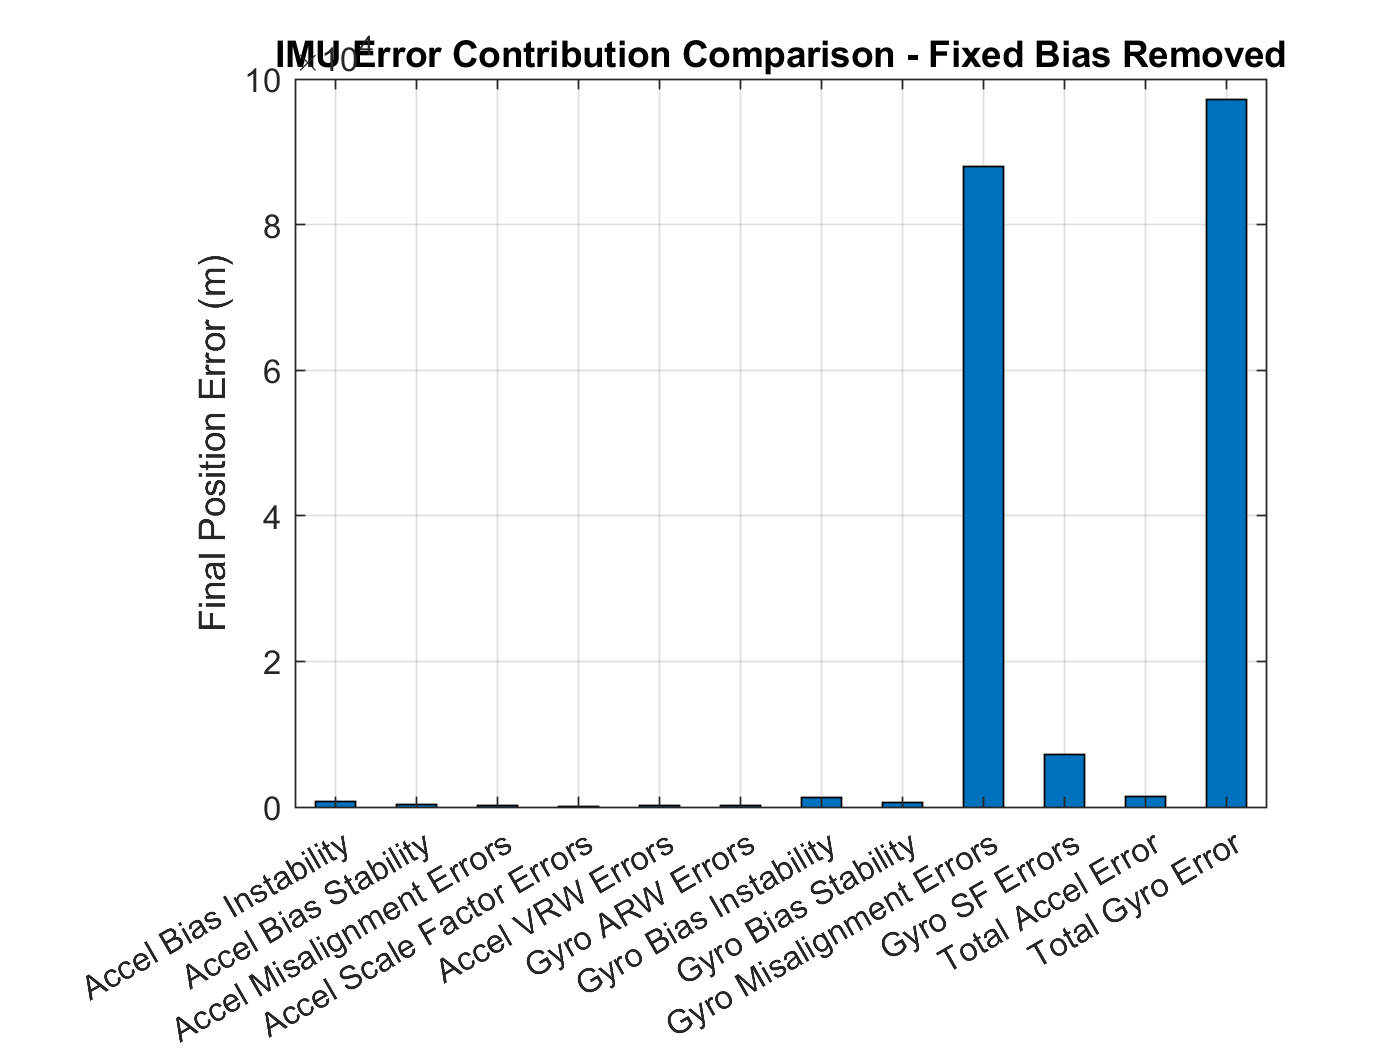

% Creating the Bar Chart
error_comp = [accel_error_comp_2(1:5), gyro_error_comp_2(1:5), total_accel_error_2, total_gyro_error_2];
labels = categorical({'Accel Bias Stability', 'Accel Bias Instability', 'Accel Scale Factor Errors', 'Accel Misalignment Errors', ...
          'Accel VRW Errors', 'Gyro Bias Stability', 'Gyro Bias Instability', 'Gyro SF Errors', 'Gyro Misalignment Errors', ...
          'Gyro ARW Errors', 'Total Accel Error', 'Total Gyro Error'});   
      
figure
bar(labels, error_comp, 0.5);
title('IMU Error Contribution Comparison - Fixed Bias Removed')
ylabel('Final Position Error (m)')
grid on

### Full IMU Calibration - Error Contribution Comparison

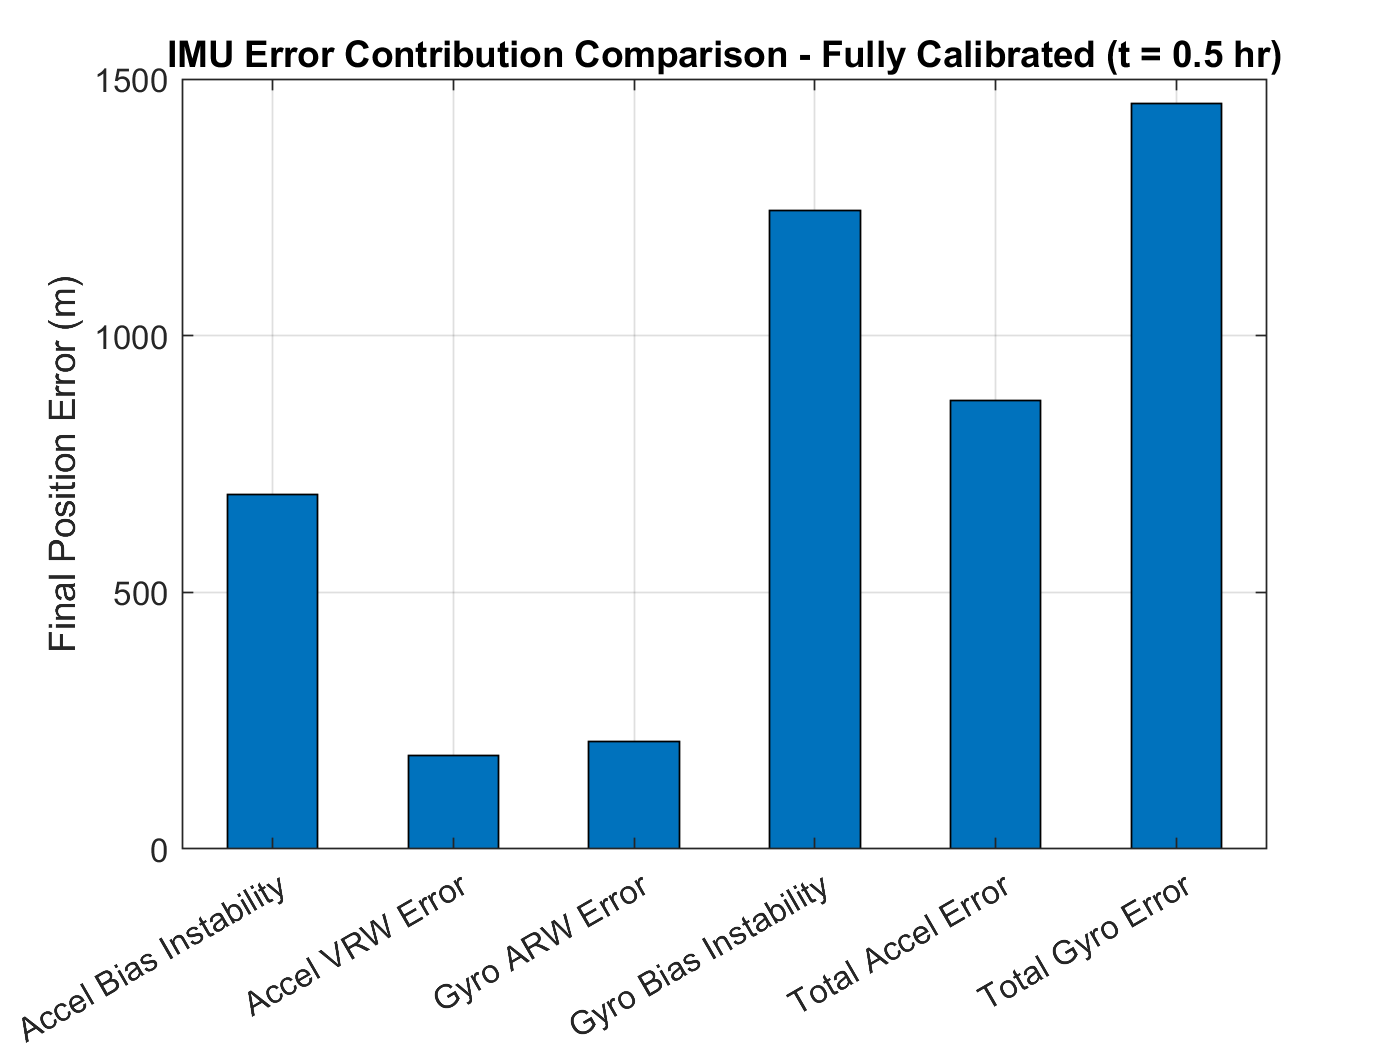

% Create the Same Graph for a Calibrated IMU
total_accel_error_3 = accel_BI_effect + accel_VRW_effect;
total_gyro_error_3 = gyro_BI_effect + gyro_ARW_effect;

% Creating the Bar Chart
error_comp_3 = [accel_BI_effect, accel_VRW_effect, ...
                gyro_BI_effect, gyro_ARW_effect, ...
                total_accel_error_3, total_gyro_error_3];
labels = categorical({'Accel Bias Instability', 'Accel VRW Error', 'Gyro Bias Instability', ...
          'Gyro ARW Error', 'Total Accel Error', 'Total Gyro Error'});   
      
figure
bar(labels, error_comp_3, 0.5);
%title('IMU Error Contribution Comparison - Fully Calibrated (t =  hr)')
% ASW: put time into plot title
title(sprintf('IMU Error Contribution Comparison - Fully Calibrated (t = %.1f hr)', t/3600))
ylabel('Final Position Error (m)')
grid on